# CIELAB error metric plots

The **CIELAB** color space and its associated distance ($\Delta E_{ab}$) are widely used to specify color discrimination. To compute the CIELAB distance we start with the CIE XYZ values and a white point that represents the subjects state of adaptation. This script plots the iso $\Delta E_{ab}$ contours around different coordinates in XYZ space and on the chromaticity diagram.

These plots illustrate the non-uniformity of color discrimination in **CIE XYZ** space, and the need for a nonlinear metric (CIELAB).  Although there are now modern extensions (e.g., CIECAM02), CIELAB remains in wide use.

**See also:**

   ieLAB2XYZ, ieCirclePoints, ieDrawShape, daylight 

ieInit

## Choose a white point for the calculation

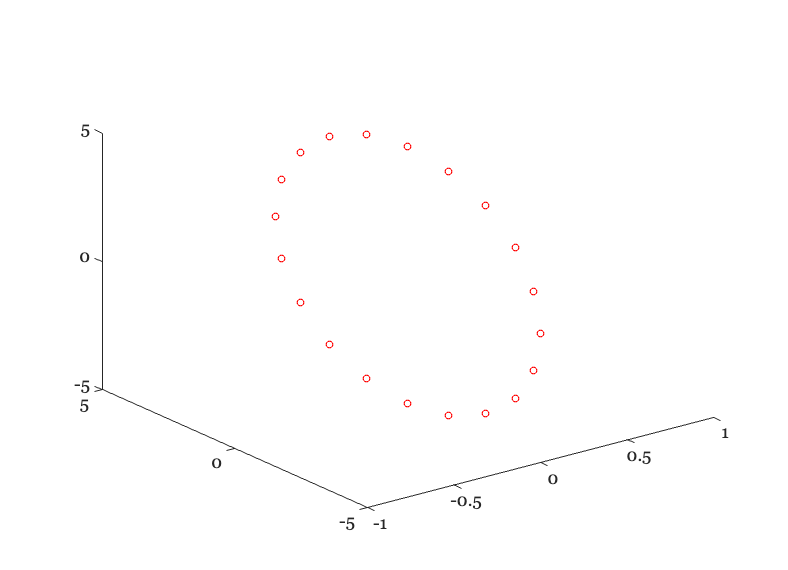

% Blackbody, 5000K
wave = 400:10:700;
[~, whiteXYZ] = daylight(wave,5000);

% Make circle of points in (a,b) coordinates
nSamples = 20;
radSpacing = 2*pi/nSamples;  % Radial spacing
[a,b] = ieCirclePoints(radSpacing);
% ieNewGraphWin; plot(a,b,'o'); axis equal

% Put them at the proper radius
dE = 5;
dAB = dE*[a(:),b(:)];
dLab = cat(2,zeros(size(dAB,1),1),dAB);
ieNewGraphWin; plot3(dLab(:,1),dLab(:,2),dLab(:,3),'o');

## Choose the Lab centers

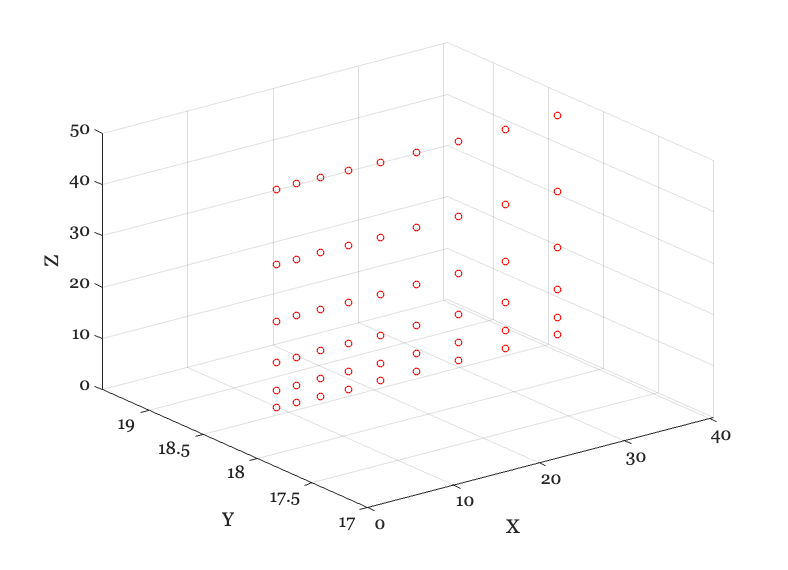

% Alternate values you could try
%{
 amn = -80;
 amx =  80;
 bmn = -90;
 bmx =  90;
 L   =  70;
%}

% Minimum and maximum ranges for a,b coordinates
amn = -70;
amx =  90;
bmn = -50;
bmx =  50;
L   =  50;

[a,b] = meshgrid(amn:20:amx,bmn:20:bmx);
AB    = [a(:), b(:)];
lab0 = cat(2,L*ones(size(AB,1),1),AB);

% Convert the LAB points into XYZ points
XYZ0 = ieLAB2XYZ(lab0,whiteXYZ);

% Plot the XYZ points
ieNewGraphWin; 
plot3(XYZ0(:,1),XYZ0(:,2),XYZ0(:,3),'o');
xlabel('X'); ylabel('Y'); zlabel('Z'); grid on

nCenters = size(lab0,1);
nSamp    = size(dLab,1);

## XYZ plot

These are CIELAB circles plotted in XYZ space.  The example is created from a single Y (luminance) plane, with circles at different X,Z positions.

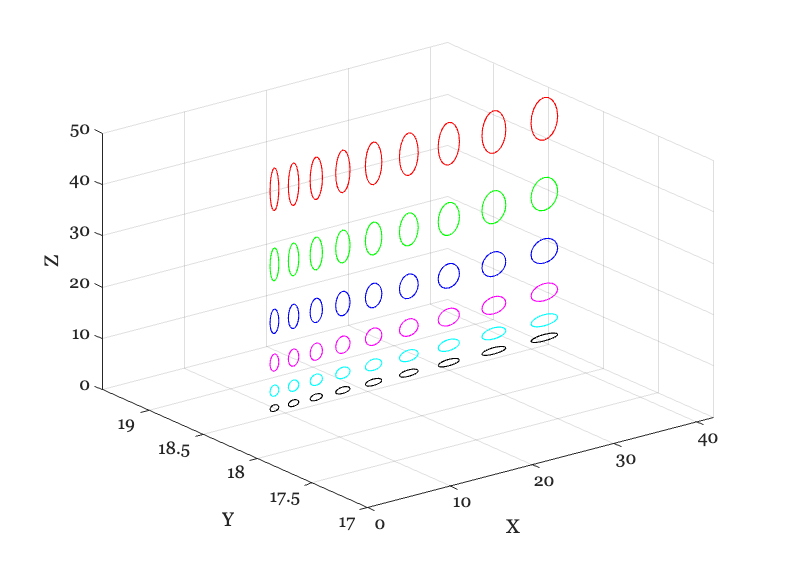

ieNewGraphWin;
for ii = 1:nCenters
    lab  = dLab + repmat(lab0(ii,:),[nSamp,1]);
    xyz = ieLAB2XYZ(lab,whiteXYZ);
    % Just the points.
    plot3(xyz(:,1),xyz(:,2),xyz(:,3),'-'); grid on
    hold on
end
xlabel('X'); ylabel('Y'); zlabel('Z');

## Chromaticity plot (x,y)

What do these circles look like in the chromaticity plane?

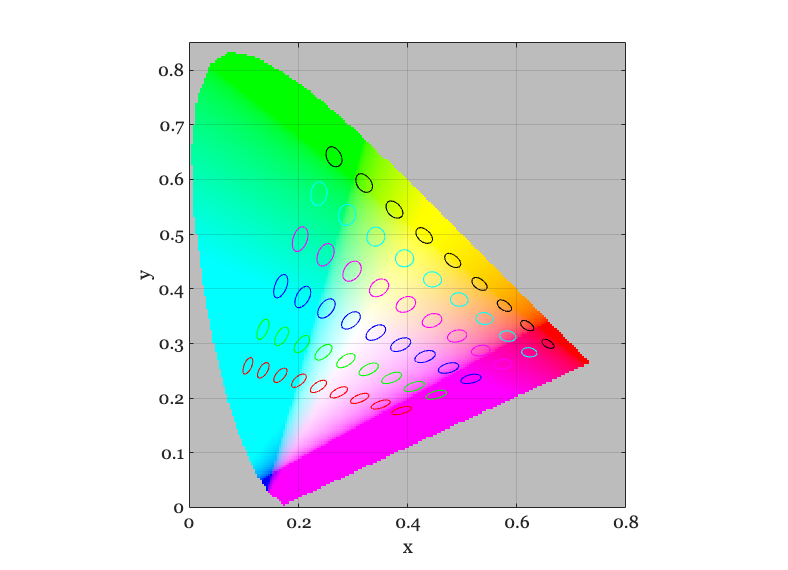

chromaticityPlot; hold on
for ii = 1:nCenters
    lab  = dLab + repmat(lab0(ii,:),[nSamp,1]);
    xy = chromaticity(ieLAB2XYZ(lab,whiteXYZ));
    % Just the points.
    plot(xy(:,1),xy(:,2),'-'); grid on
    hold on
end
xlabel('x'); ylabel('y');

## Visualize the points on a sphere in Lab space

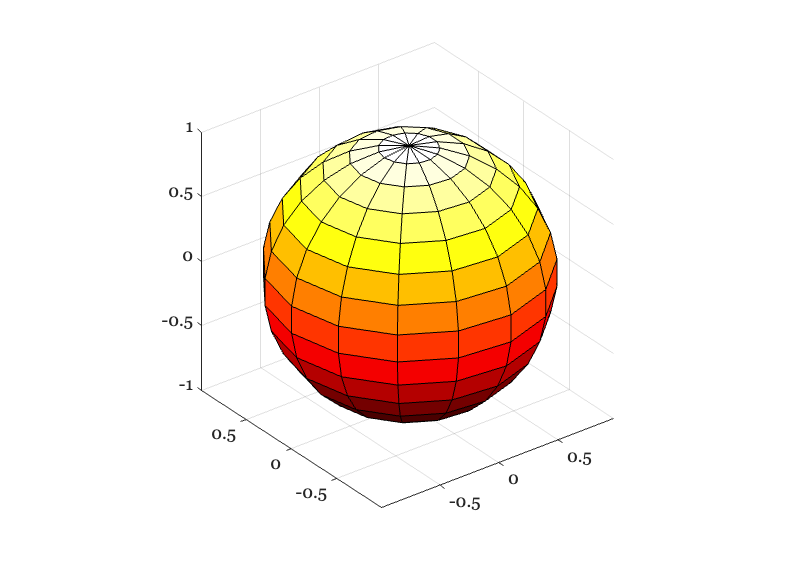

N = 15;
[L, a, b] = sphere(N);
ieNewGraphWin;
surf(L,a,b); colormap(hot(64)); axis equal

% These are the sphere points at 5 dE
dLab    = 2*[L(:),a(:),b(:)];
nSamp = size(dLab,1);

## Visualize multiple spheres with centers at different LAB locations in XYZ

These CIELAB spheres have different sizes and shapes as we change the luminance and X,Z center.

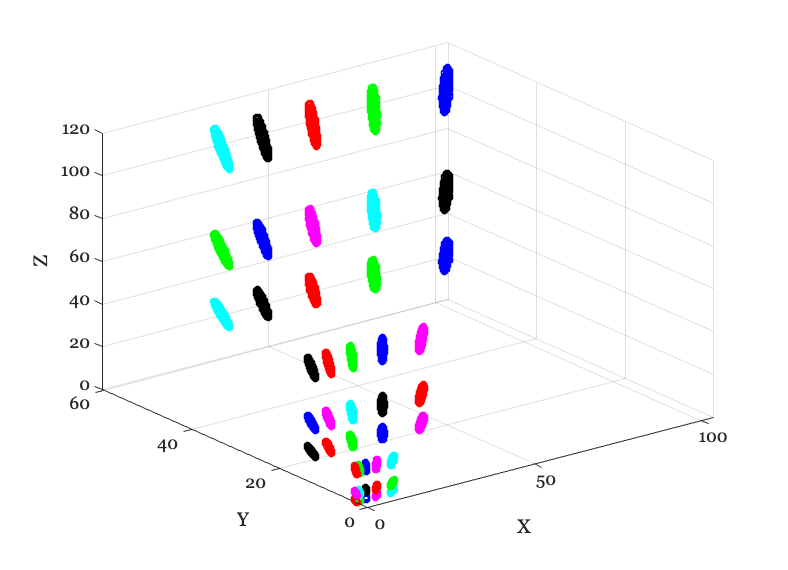

% Make the centers, widely spaced for this 3D case
amn = -70;
amx =  90;
bmn = -50;
bmx = 50;
Lmn = 20;
Lmx = 80;

[L,a,b] = meshgrid(Lmn:30:Lmx,amn:40:amx,bmn:40:bmx);
lab0    = [L(:), a(:), b(:)];
nCenters = size(lab0,1);

ieNewGraphWin;
for ii = 1:nCenters
    lab  = dLab + repmat(lab0(ii,:),[nSamp,1]);
    XYZ = ieLAB2XYZ(lab,whiteXYZ);
    
    % Just the points.
    plot3(XYZ(:,1),XYZ(:,2),XYZ(:,3),'o'); grid on
    hold on
end
xlabel('X'); ylabel('Y'); zlabel('Z')